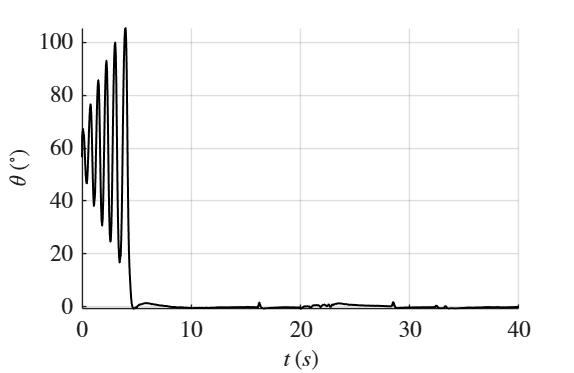

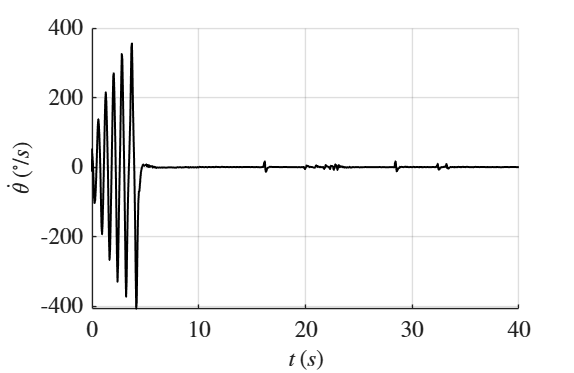

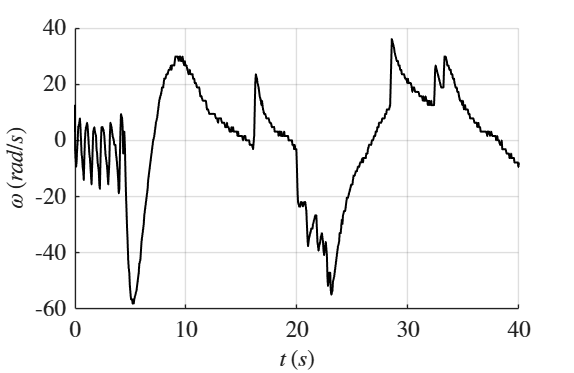

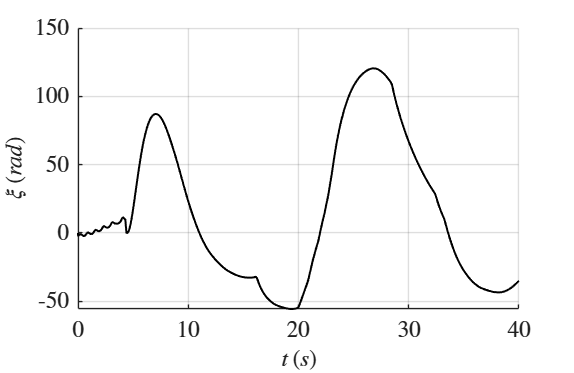

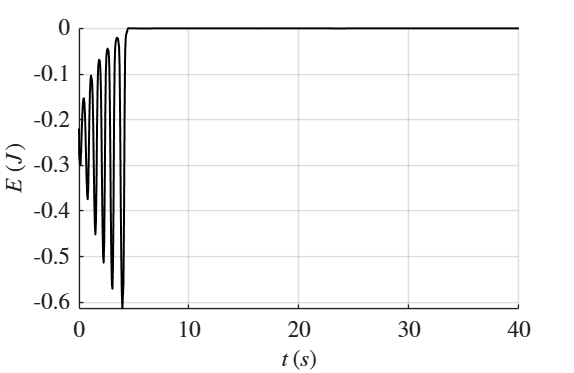

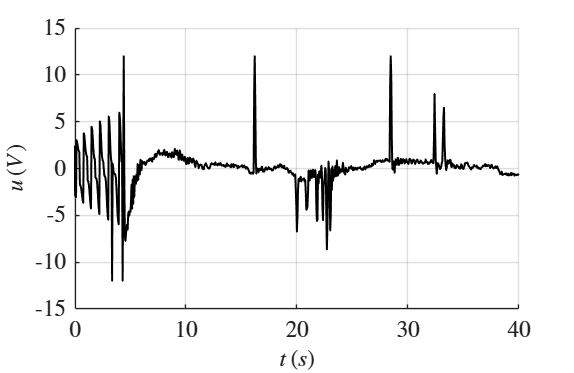

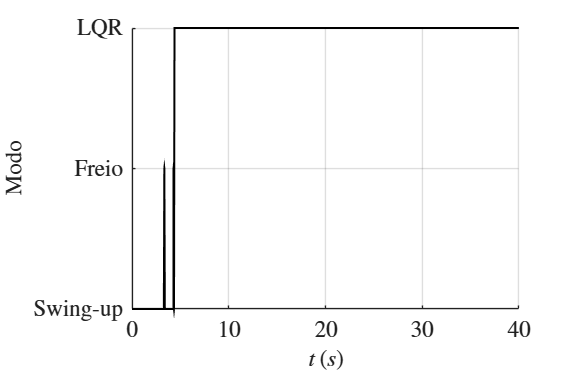

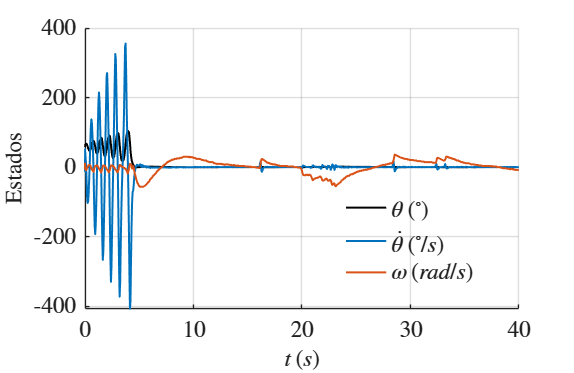

Gráficos experimentais gerados com sucesso.


% =========================================================================
%  Geração dos gráficos experimentais da planta
% =========================================================================
%
%  Este script realiza o processamento dos dados experimentais coletados do
%  triângulo autoequilibrante e gera os gráficos utilizados no capítulo de
%  resultados da monografia.
%
%  A entrada do código é um arquivo CSV gerado pelo script de coleta serial,
%  contendo as variáveis transmitidas pelo ESP32 durante o ensaio
%  experimental. O arquivo deve possuir as seguintes colunas:
%
%    tempo_s
%    modo
%    theta_rad
%    theta_dot_rad_s
%    omega_rad_s
%    xi_rad
%    energia_J
%    u_V
%
%  A partir desses dados, o script converte as variáveis angulares do corpo
%  para graus, ajusta o vetor de tempo para iniciar em zero e gera figuras
%  individuais em formato PDF. Os arquivos gerados são utilizados diretamente
%  na seção de resultados experimentais.
%
%  Saídas geradas:
%    - resultado_theta_experimental.pdf
%    - resultado_theta_dot_experimental.pdf
%    - resultado_omega_experimental.pdf
%    - resultado_xi_experimental.pdf
%    - resultado_energia_experimental.pdf
%    - resultado_controle_experimental.pdf
%    - resultado_modo_experimental.pdf
%    - resultado_estados_experimental.pdf
%
% =========================================================================

clc;
clear;
close all;

%% Leitura do arquivo CSV experimental

[arquivo, caminho] = uigetfile('*.csv', 'Selecione o arquivo CSV');

if isequal(arquivo, 0)
    error('Nenhum arquivo foi selecionado.');
end

dados = readtable(fullfile(caminho, arquivo));

t = dados.tempo_s;
modo = dados.modo;
theta = dados.theta_rad;
theta_dot = dados.theta_dot_rad_s;
omega = dados.omega_rad_s;
xi = dados.xi_rad;
energia = dados.energia_J;
u = dados.u_V;

theta_graus = rad2deg(theta);
theta_dot_graus = rad2deg(theta_dot);

t = t - t(1);

%% Configuração gráfica para exportação

picturewidth = 20;
hw_ratio = 0.65;

%% Figura 1 - Ângulo da planta

hfig = figure;

plot(t, theta_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\theta \, (^\circ)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 2 - Velocidade angular do corpo

hfig = figure;

plot(t, theta_dot_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_dot_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 3 - Velocidade angular da roda de reação

hfig = figure;

plot(t, omega, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_omega_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 4 - Estado associado à posição acumulada da roda

hfig = figure;

plot(t, xi, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\xi \, (rad)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_xi_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 5 - Energia mecânica da planta

hfig = figure;

plot(t, energia, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$E \, (J)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_energia_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 6 - Sinal de controle aplicado ao motor

hfig = figure;

plot(t, u, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$u \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_controle_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 7 - Modo de operação ativo

hfig = figure;

stairs(t, modo, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('Modo', 'Interpreter', 'latex');

yticks([0 1 2]);
yticklabels({'Swing-up', 'Freio', 'LQR'});

grid on;

fname = 'resultado_modo_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 8 - Resposta conjunta dos principais estados

hfig = figure;

plot(t, theta_graus, '-', 'Color', [0 0 0], 'LineWidth', 1.5);
hold on;
plot(t, theta_dot_graus, '-', 'Color', [0 0.4470 0.7410], 'LineWidth', 1.5);
plot(t, omega, '-', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
hold off;

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('Estados', 'Interpreter', 'latex');

legend('$\theta \, (^\circ)$', ...
       '$\dot{\theta} \, (^\circ/s)$', ...
       '$\omega \, (rad/s)$', ...
       'Interpreter', 'latex', ...
       'Location', 'best');

grid on;

fname = 'resultado_estados_experimental';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

disp('Gráficos experimentais gerados com sucesso.');